# Analysis of the connection of two pipes

close all;
clear all;
clc;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_3_pipes_height_38um_pulse_5s_rectangular_tetrazine_Design_2');

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_3_pipes_height_38um_pulse_5s_rectangular_tetrazine_Design_2


#### Parameters

%call to the parameters file
Parameters

p0 = 600

mu = 9.9792e-04

D_coeff = 4.9000e-10

#### Length and width per pipe

%Pipe_1
%width
w_1=0;
[var,factor]=getVarTable(w_1,table);
w_1=eval(var{1})*factor

w_1 = 1.6767e-04

%heigth
height_pipe=0;
[var,factor]=getVarTable(height_pipe,table);
height_pipe=eval(var{1})*factor

height_pipe = 3.8000e-05

%Length
L_1=0;
[var,factor]=getVarTable(L_1,table);
L_1=eval(var{1})*factor

L_1 = 0.0177


%Pipe_2
%width
w_2=0;
[var,factor]=getVarTable(w_2,table);
w_2=eval(var{1})*factor

w_2 = 1.9489e-04

%Length
L_2=0;
[var,factor]=getVarTable(L_2,table);
L_2=eval(var{1})*factor

L_2 = 0.0252

%Angle
varphi_2=0;
[var,factor]=getVarTable(varphi_2,table);
varphi_2=eval(var{1})*factor

varphi_2 = 1.5907


%Pipe_3
%width
w_3=0;
[var,factor]=getVarTable(w_3,table);
w_3=eval(var{1})*factor

w_3 = 1.6737e-04

%Length
L_3=0;
[var,factor]=getVarTable(L_3,table);
L_3=eval(var{1})*factor

L_3 = 0.0305

%Angle
varphi_3=0;
[var,factor]=getVarTable(varphi_3,table);
varphi_3=eval(var{1})*factor

varphi_3 = 1.9077

#### Flow rate for a given pressure drop  

**Description:** This block assumes a syringe is connected to the inlet of the pipe and introduces a constant flow rate Q. The pressure formula follows the Hagen–Poiseuille equation [1, Table 3.1 pp. 43]

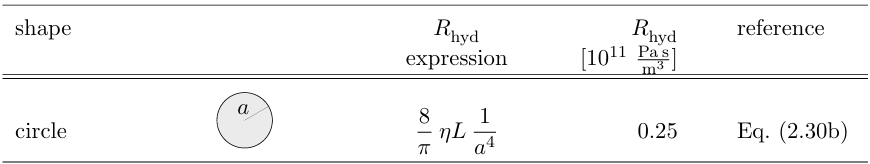

$\Delta P=RQ
$, (1)

where $R$ denotes the pipe resistance and is given as follows

- Rectangular cross-shape $R=\frac{12\mu L}{1-0.63\frac{h}{w}}\cdot\frac{1}{h^3w}$, $w\gg h$

- Circular cross-shape $R=\frac{8\mu L}{\pi r^4}$

where 

$\mu$ is the water viscosity,

$L$ is the channel length,

$r$ is the radius of a circular pipe.

$h$ is the height of a rectangular pipe

$w$ is the width of a rectangular pipe

%resistance of the rectangular Pipe 1
R_1=12*mu_Water*L_1/(1-0.63*height_pipe/w_1)*(1/(height_pipe^3*w_1))

R_1 = 2.6817e+13

%resistance of the rectangular Pipe 2
R_2=12*mu_Water*L_2/(1-0.63*height_pipe/w_2)*(1/(height_pipe^3*w_2))

R_2 = 3.2207e+13

%resistance of the rectangular Pipe 3
R_3=12*mu_Water*L_3/(1-0.63*height_pipe/w_3)*(1/(height_pipe^3*w_3))

R_3 = 4.6448e+13


% Equivalent parallel resistance
Req = 1 / sum(1 ./ [R_1 R_2 R_3])

Req = 1.1127e+13


%evaluating the extra hydraulic resistance
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = 'polygon_outer.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
x_pol_outer=table.Var1;
y_pol_outer=table.Var2;

% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = 'polygon_upper.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
x_pol_upper=table.Var1;
y_pol_upper=table.Var2;

%length of the inlet
L_in_Pipe_1=abs(x_pol_outer(10)-x_pol_upper(1)) %inlet connection to pipe 1

L_in_Pipe_1 = 5.6511e-04

L_in_Pipe_1=abs(x_pol_outer(2)-x_pol_outer(1))/3 %inlet connection to pipe 1

L_in_Pipe_1 = 7.0000e-05

L_in=x_pol_outer(2)-x_pol_outer(1) %inlet connection to Pipes 2 and 3

L_in = 2.1000e-04

%w_in=(abs(y_pol_outer(1)-y_pol_outer(10))+abs(y_pol_upper(1)-y_pol_outer(10)))
w_in=2*abs(y_pol_upper(1)-y_pol_outer(10))

w_in = 3.6566e-04

% w_in=(abs(y_pol_outer(1)-y_pol_outer(10)))
%length of the outlet
L_out=x_pol_outer(5)-x_pol_outer(4)

L_out = 2.1000e-04

w_out=abs(y_pol_outer(6)-y_pol_outer(5))

w_out = 9.8995e-05

%inlet resistance to Pipe 1
R_in_Pipe_1=12*mu_Water*L_in_Pipe_1/(1-0.63*height_pipe/w_in)*(1/(height_pipe^3*w_in))

R_in_Pipe_1 = 4.4705e+10

%inlet resistance to Pipes 2 and 3
R_in=12*mu_Water*L_in/(1-0.63*height_pipe/w_in)*(1/(height_pipe^3*w_in))

R_in = 1.3411e+11

%outlet resistance
R_out=12*mu_Water*L_out/(1-0.63*height_pipe/w_out)*(1/(height_pipe^3*w_out))

R_out = 6.1061e+11



% Total flow to the three pipes
Q_T=p0/Req

Q_T = 5.3921e-11

Q_T_uL_min=Q_T*6e10

Q_T_uL_min = 3.2352


%Flow to the pipe 1 in a single connection
Q_1=p0/R_1;
Q_1_uL_min=Q_1*6e10

Q_1_uL_min = 1.3424



%Flow to the pipe 2 in a single connection
Q_2=p0/(R_in+R_out+Req)*Req/R_2;
Q_2_uL_min=Q_2*6e10

Q_2_uL_min = 1.0477



%Flow to the pipe 2 in a single connection
Q_3=p0/(R_in+R_out+Req)*Req/R_3;
Q_3_uL_min=Q_3*6e10

Q_3_uL_min = 0.7264

## 3D Pipe 1, 2, 3

### COMSOL simulation

%Pipe 1
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = '3D_Pipe_1_Outlet_Concentration_Surface_Average.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_1_COMSOL=table.Var2;
%CIR
h_cir_1_COMSOL=gradient(conc_Pipe_1_COMSOL,time);

%Pipe 2
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = '3D_Pipe_2_Outlet_Concentration_Surface_Average.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_2_COMSOL=table.Var2;
%CIR
h_cir_2_COMSOL=gradient(conc_Pipe_2_COMSOL,time);

%Pipe 3
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = '3D_Pipe_3_Outlet_Concentration_Surface_Average.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_3_COMSOL=table.Var2;
%CIR
h_cir_3_COMSOL=gradient(conc_Pipe_3_COMSOL,time);


### Theoretical calculations

%Pipe 1
%mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q_1/(w_1*height_pipe)

v_char = 0.0035


%Peclet number, see [3, Eq. below 11] 
Pe=v_char*height_pipe/D_coeff;

%Evaluating the Effective Diffusion coefficient
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2);

%Evaluating the concentration of the straigth channel
conc_Pipe_1_Theo=1./2.*erfc((L_1-v_char*time)./(2*sqrt(D_eff*time)));
% %Evaluating the channel impulse response
h_cir_1_Theo=gradient(conc_Pipe_1_Theo,time);

%finding the maximum
tau_1=L_1/v_char-2*D_eff/v_char^2;
[~,idx]=min(abs(time-tau_1));
peak_1=h_cir_1_Theo(idx);

%Pipe 2
%mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q_2/(w_2*height_pipe)

v_char = 0.0024

%Peclet number, see [3, Eq. below 11] 
Pe=v_char*height_pipe/D_coeff;
%Evaluating the Effective Diffusion coefficient
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2);

%Matlab code to evaluate the integral
syms t x rd v varphi D C_0 w
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(w)*int(integrand, rd, 0, w));
%Performing the integral
c_avg=1/(w)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[w,1])-subs(c_avg,[rd,C_0],[0,1]);
c_avg_param_int_Pipe_2=subs(c_avg_int,[x,D,v,w,varphi],[L_2,D_eff,v_char,w_2,varphi_2]);
conc_Pipe_2_Theo=double(subs(c_avg_param_int_Pipe_2,[t],[time(2:end)]));

%Evaluating the concentration of the straigth channel
% conc_Pipe_2_Theo=1./2.*erfc((L_2-v_char*time)./(2*sqrt(D_eff*time)));
% %Evaluating the channel impulse response
h_cir_2_Theo=gradient(conc_Pipe_2_Theo,time(2:end));
%finding the maximum
tau_2=L_2/v_char-2*D_eff/v_char^2;
[~,idx]=min(abs(time-tau_2));
peak_2=h_cir_2_Theo(idx);

%Pipe 3
%mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q_3/(w_3*height_pipe)

v_char = 0.0019


%Peclet number, see [3, Eq. below 11] 
Pe=v_char*height_pipe/D_coeff;

%Evaluating the Effective Diffusion coefficient
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2);

%Matlab code to evaluate the integral
syms t x rd v varphi D C_0 w
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(w)*int(integrand, rd, 0, w));
%Performing the integral
c_avg=1/(w)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[w,1])-subs(c_avg,[rd,C_0],[0,1]);
c_avg_param_int_Pipe_3=subs(c_avg_int,[x,D,v,w,varphi],[L_3,D_eff,v_char,w_3,varphi_3]);
conc_Pipe_3_Theo=double(subs(c_avg_param_int_Pipe_3,[t],[time(2:end)]));

% %Evaluating the concentration of the straigth channel
% conc_Pipe_3_Theo=1./2.*erfc((L_3-v_char*time)./(2*sqrt(D_eff*time)));
% %Evaluating the channel impulse response
h_cir_3_Theo=gradient(conc_Pipe_3_Theo,time(2:end));

%finding the maximum
tau_3=L_3/v_char-2*D_eff/v_char^2;
[~,idx]=min(abs(time-tau_3));
peak_3=h_cir_3_Theo(idx);

### Plots

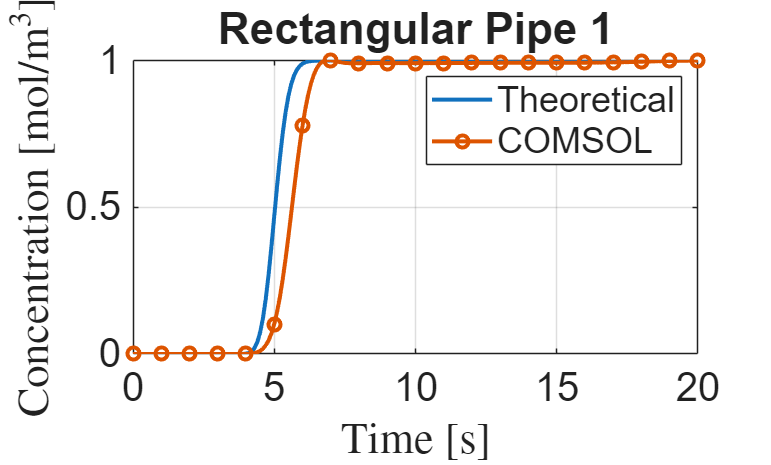

%Pipe 1
figure;
plot(time,conc_Pipe_1_Theo,'LineWidth',2); grid on; hold on;
plot(time,conc_Pipe_1_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL)); grid on;
xlabel("Time [s]",'Interpreter','latex');
ylabel("Concentration [mol/m$^3$]",'Interpreter','latex');
title("Rectangular Pipe 1")
legend({'Theoretical','COMSOL'},'Location','northeast');
set(gca,'FontSize',fontsize);

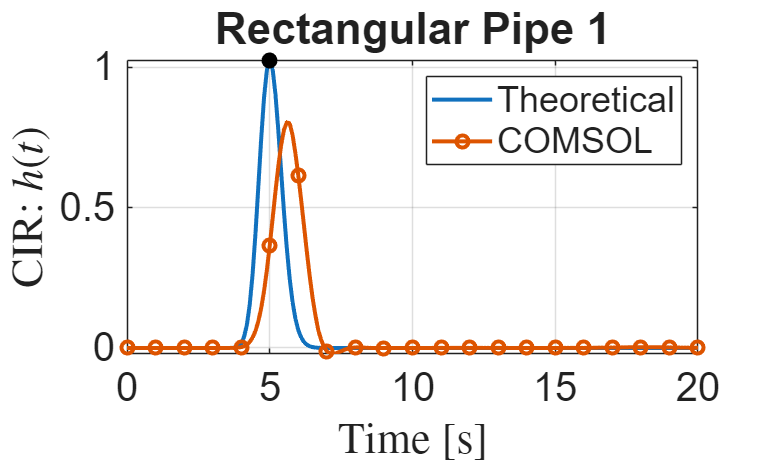


figure;
plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
plot(time,h_cir_1_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL));
plot(tau_1,peak_1,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
xlabel("Time [s]",'Interpreter','latex');
ylabel("CIR: $h(t)$",'Interpreter','latex');
title("Rectangular Pipe 1")
set(gca,'FontSize',fontsize);
legend({'Theoretical','COMSOL'},'Location','northeast');

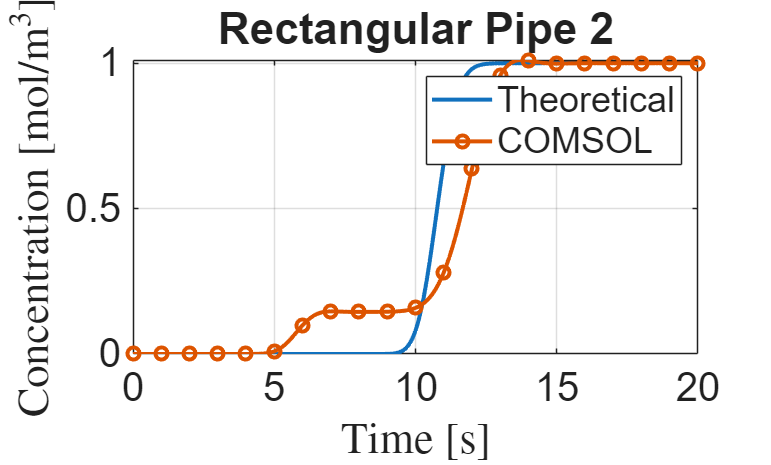


%Pipe 2
figure;
plot(time(2:end),conc_Pipe_2_Theo,'LineWidth',2); grid on; hold on;
plot(time,conc_Pipe_2_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL)); grid on;
xlabel("Time [s]",'Interpreter','latex');
ylabel("Concentration [mol/m$^3$]",'Interpreter','latex');
title("Rectangular Pipe 2")
legend({'Theoretical','COMSOL'},'Location','northeast');
set(gca,'FontSize',fontsize);

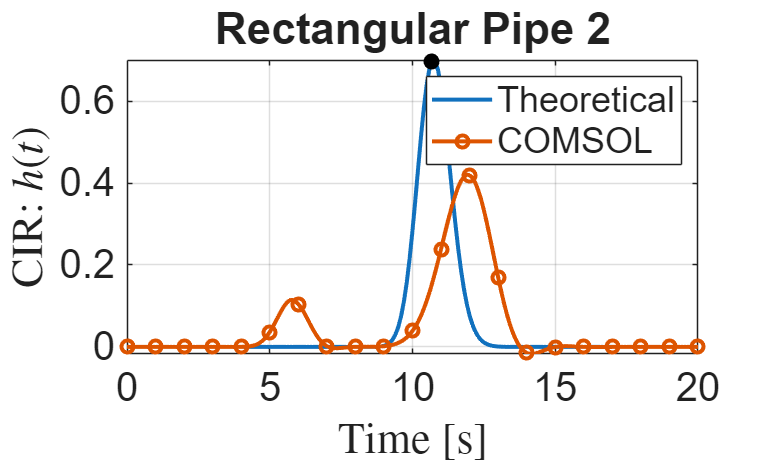


figure;
plot(time(2:end),h_cir_2_Theo,'LineWidth',2); grid on; hold on;
plot(time,h_cir_2_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL));
plot(tau_2,peak_2,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
xlabel("Time [s]",'Interpreter','latex');
ylabel("CIR: $h(t)$",'Interpreter','latex');
title("Rectangular Pipe 2")
set(gca,'FontSize',fontsize);
legend({'Theoretical','COMSOL'},'Location','northeast');

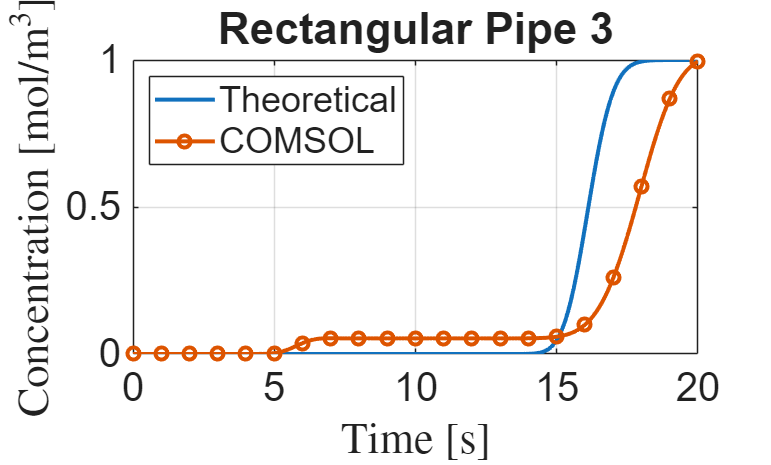


%Pipe 3
figure;
plot(time(2:end),conc_Pipe_3_Theo,'LineWidth',2); grid on; hold on;
plot(time,conc_Pipe_3_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL)); grid on;
xlabel("Time [s]",'Interpreter','latex');
ylabel("Concentration [mol/m$^3$]",'Interpreter','latex');
title("Rectangular Pipe 3")
legend({'Theoretical','COMSOL'},'Location','northwest');
set(gca,'FontSize',fontsize);

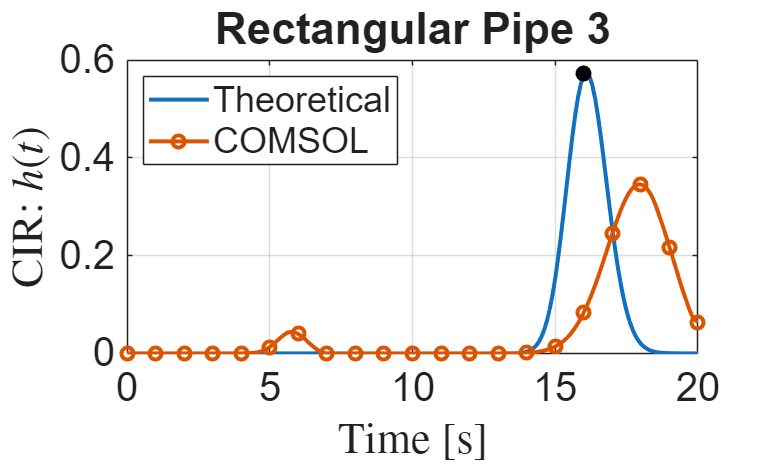


figure;
plot(time(2:end),h_cir_3_Theo,'LineWidth',2); grid on; hold on;
plot(time,h_cir_3_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL));
plot(tau_3,peak_3,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
xlabel("Time [s]",'Interpreter','latex');
ylabel("CIR: $h(t)$",'Interpreter','latex');
title("Rectangular Pipe 3")
set(gca,'FontSize',fontsize);
legend({'Theoretical','COMSOL'},'Location','northwest');

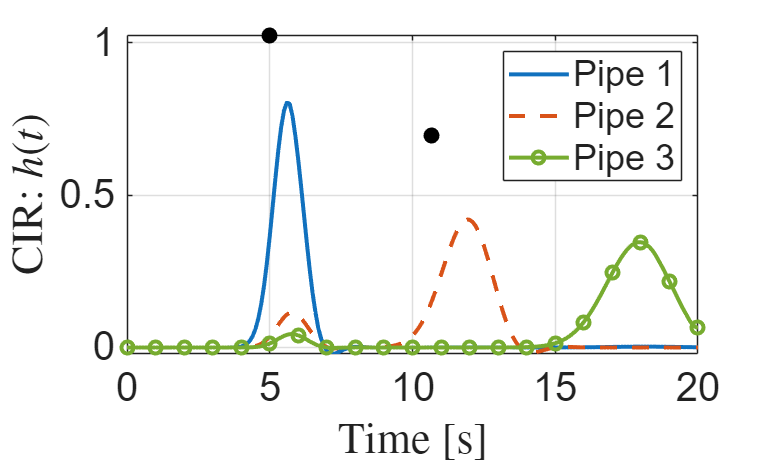


figure;
p1=plot(time,h_cir_1_COMSOL,'-','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL));grid on; hold on;
plot(tau_1,peak_1,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
p2=plot(time,h_cir_2_COMSOL,'--','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL),'Color',"#D95319");
plot(tau_2,peak_2,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
p3=plot(time,h_cir_3_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL),'Color',"#77AC30");
plot(tau_3,peak_3,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
xlabel("Time [s]",'Interpreter','latex');
ylabel("CIR: $h(t)$",'Interpreter','latex');
set(gca,'FontSize',fontsize);
legend([p1,p2,p3],{'Pipe 1','Pipe 2','Pipe 3'},'Location','northeast');

## Calculating the correction

% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = '3D_Pipe_1_Outlet_Concentration_Surface_Average.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;

%Pipe 1
%COMSOL calculations
[~,idx]=max(h_cir_1_COMSOL);
tau_1_COMSOL=time(idx);
delta_tau_1=tau_1-tau_1_COMSOL

delta_tau_1 = -0.6000

%Calculating the new length
%coefficients
geom_factor = 1 - 0.63*height_pipe/w_1;
K = p0 * geom_factor * height_pipe^2 / (12*mu_Water);   % [m^2/s]
A = 1/K - 2*D_coeff / K^2;                               % [s/m^2]
%B = - height_pipe^2 / (100*D_coeff);                     % [s]
%tau_1_base = A .* L_1.^2 + B;   % [s]
arg = L_1.^2 + delta_tau_1./A;
L1_new  = sqrt(arg)

L1_new = 0.0166

Delta_L1 = L1_new - L_1

Delta_L1 = -0.0011


%Pipe 2
[~,idx]=max(h_cir_2_COMSOL);
tau_2_COMSOL=time(idx);
delta_tau_2=tau_2-tau_2_COMSOL

delta_tau_2 = -1.2288

%Calculating the new length
%coefficients
geom_factor = 1 - 0.63*height_pipe/w_2;
K = p0 * geom_factor * height_pipe^2 / (12*mu_Water);   % [m^2/s]
A = 1/K - 2*D_coeff / K^2;                               % [s/m^2]
%B = - height_pipe^2 / (100*D_coeff);                     % [s]
%tau_1_base = A .* L_1.^2 + B;   % [s]
arg = L_2.^2 + delta_tau_2./A;
L2_new  = sqrt(arg)

L2_new = 0.0236

Delta_L2 = L2_new - L_2

Delta_L2 = -0.0016


%Pipe 3
[~,idx]=max(h_cir_3_COMSOL);
tau_3_COMSOL=time(idx);
delta_tau_3=tau_3-tau_3_COMSOL

delta_tau_3 = -1.8942

%Calculating the new length
%coefficients
geom_factor = 1 - 0.63*height_pipe/w_3;
K = p0 * geom_factor * height_pipe^2 / (12*mu_Water);   % [m^2/s]
A = 1/K - 2*D_coeff / K^2;                               % [s/m^2]
%B = - height_pipe^2 / (100*D_coeff);                     % [s]
%tau_1_base = A .* L_1.^2 + B;   % [s]
arg = L_3.^2 + delta_tau_3./A;
L3_new  = sqrt(arg)

L3_new = 0.0285

Delta_L3 = L3_new - L_3

Delta_L3 = -0.0020

# CAD design of the CNN-like structure

**Description:** This code evaluates the coordinates for the upper lines and lower lines for each pipe. As represented on Fig. 1, we define each pipe coordinates with points.

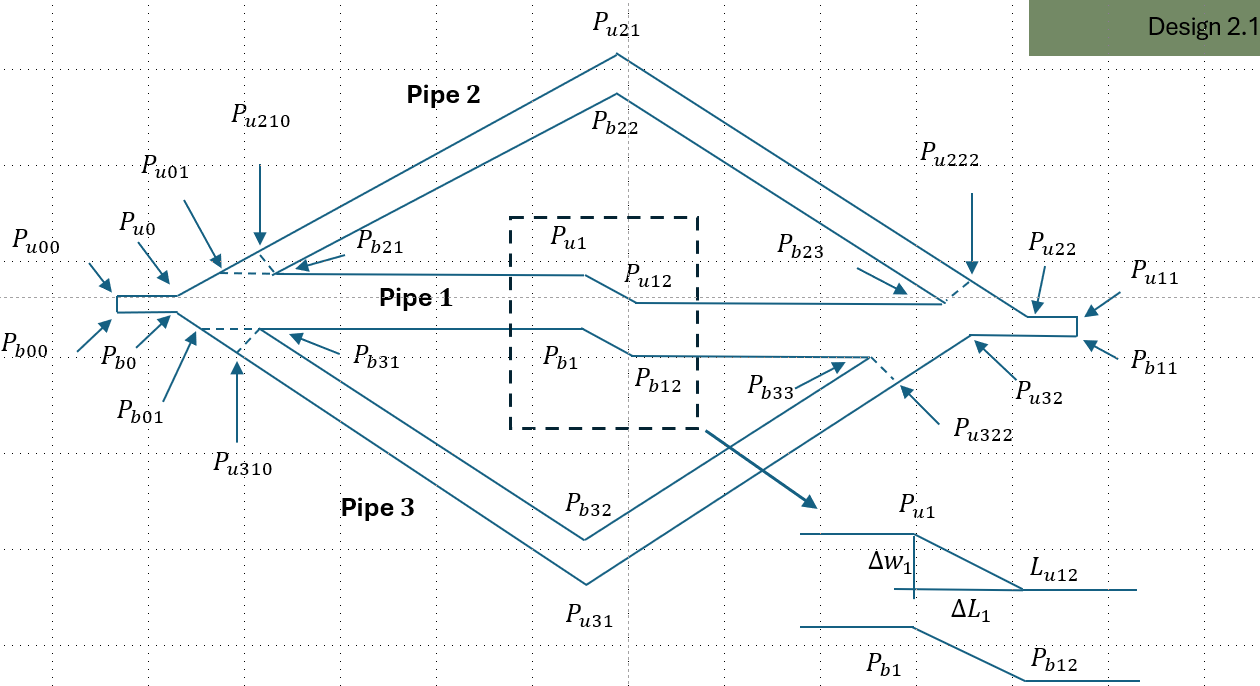

Figure 1: Reference points on the design.

## Asigning the new dimensions

L_1=L1_new;
L_2=L2_new;
L_3=L3_new;

## Parameters related to the flow in Pipe 1

delta_w1_y=w_1/2;
delta_L1_x=2*delta_w1_y;

## Reference coordinates

%this reference coordinates are coming from the original CAD desing. This
%two points reference refer to the pipe just after the mixer on the
%transmitter side. See Fig. 1.
P_u0=[-42.36063776 1.75826183]*1e-3;
P_b0=[-42.36063776 1.65926683]*1e-3;
%width for the mixer pipe, this is taken from [4]
w_0=P_u0(2)-P_b0(2);

fprintf('P_u0\n')

P_u0


fprintf('%.8f', P_u0(1)*1e3);   % fixed-point with 15 decimals

-42.36063776

fprintf('%.8f', P_u0(2)*1e3);   % fixed-point with 15 decimals

1.75826183


fprintf('P_b0\n')

P_b0


fprintf('%.8f', P_b0(1)*1e3);   % fixed-point with 15 decimals

-42.36063776

fprintf('%.8f', P_b0(2)*1e3);   % fixed-point with 15 decimals

1.65926683

## Restarting the reference coordinates

%length of the inlet
L_0=210e-6;

P_b00=[0 0];
P_u00=P_b00+[0 w_0]

P_u00 = 1.0e-04 *

         0    0.9899



fprintf('P_u00\n')

P_u00


fprintf('%.8f', P_u00(1)*1e3);   % fixed-point with 15 decimals

0.00000000

fprintf('%.8f', P_u00(2)*1e3);   % fixed-point with 15 decimals

0.09899500


fprintf('P_b0\n')

P_b0


fprintf('%.8f', P_b00(1)*1e3);   % fixed-point with 15 decimals

0.00000000

fprintf('%.8f', P_b00(2)*1e3);   % fixed-point with 15 decimals

0.00000000



P_b0=P_b00+[L_0 0];
P_u0=P_b0+[0 w_0];

fprintf('P_u0\n')

P_u0


fprintf('%.8f', P_u0(1)*1e3);   % fixed-point with 15 decimals

0.21000000

fprintf('%.8f', P_u0(2)*1e3);   % fixed-point with 15 decimals

0.09899500


fprintf('P_b0\n')

P_b0


fprintf('%.8f', P_b0(1)*1e3);   % fixed-point with 15 decimals

0.21000000

fprintf('%.8f', P_b0(2)*1e3);   % fixed-point with 15 decimals

0.00000000

## Pipe 2 coordinates

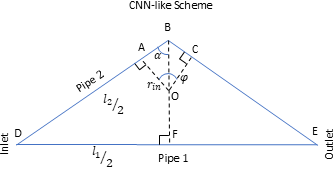

Figure 2: Reference angles within the pipe.

%heigth of the pipe
alpha=asin(L_1/L_2);
varphi_2=2*(pi-pi/2-alpha);
h_2=sqrt((L_2/2)^2-(L_1/2)^2);

P_u21=P_u0+[L_1/2 h_2];
fprintf('P_u21\n')

P_u21


fprintf('%.8f', P_u21(1)*1e3);   % fixed-point with 15 decimals

8.49740207

fprintf('%.8f', P_u21(2)*1e3);   % fixed-point with 15 decimals

8.52221251


%Calculating the point P_u01
%evaluating the line P_u0 to P_u21
m=(P_u21(2)-P_u0(2))/(P_u21(1)-P_u0(1))

m = 1.0164

b=P_u21(2)-m*P_u21(1)

b = -1.1445e-04

P_u01(2)=P_u0(2)+w_1/2;
P_u01(1)=(P_u01(2)-b)/m;
% fprintf('P_u01\n')
% fprintf('%.8f', P_u01(1)*1e3);   % fixed-point with 15 decimals
% fprintf('%.8f', P_u01(2)*1e3);   % fixed-point with 15 decimals

P_b21=P_u01+[w_2/h_2*L_2/2 0];
fprintf('P_b21\n')

P_b21


fprintf('%.8f', P_b21(1)*1e3);   % fixed-point with 15 decimals

0.56589238

fprintf('%.8f', P_b21(2)*1e3);   % fixed-point with 15 decimals

0.18282900


P_b22=P_u21+[0 -w_2/sin(alpha)];
fprintf('P_b22\n')

P_b22


fprintf('%.8f', P_b22(1)*1e3);   % fixed-point with 15 decimals

8.49740207

fprintf('%.8f', P_b22(2)*1e3);   % fixed-point with 15 decimals

8.24432170


L_u1=2*(P_b22(1)-P_b21(1));

P_u1=P_b21+[L_u1/2 0];

P_u12=P_u1+[delta_L1_x -delta_w1_y];


P_b23=P_b21+[L_u1 0]+[delta_L1_x -delta_w1_y];
fprintf('P_b23\n')

P_b23


fprintf('%.8f', P_b23(1)*1e3);   % fixed-point with 15 decimals

16.59657976

fprintf('%.8f', P_b23(2)*1e3);   % fixed-point with 15 decimals

0.09899500


P_u22=P_u0+[L_1 0]+[delta_L1_x -delta_w1_y];
fprintf('P_u22\n')

P_u22


fprintf('%.8f', P_u22(1)*1e3);   % fixed-point with 15 decimals

16.95247215

fprintf('%.8f', P_u22(2)*1e3);   % fixed-point with 15 decimals

0.01516100


%Calculating the point P_u222
%evaluating the line P_u21 to P_u22
m=(P_u21(2)-P_u22(2))/(P_u21(1)-P_u22(1))

m = -1.0061

b=P_u21(2)-m*P_u21(1)

b = 0.0171

mA = -1/m; % slope of perpendicular to line P_u21 to Pu22 
P_u222(1) = (b - P_b23(2) + mA*P_b23(1)) / (mA - m);
P_u222(2) = m*P_u222(1) + b;

%Calculating the point P_u210
%evaluating the line P_u0 to P_u21
m=(P_u0(2)-P_u21(2))/(P_u0(1)-P_u21(1))

m = 1.0164

b=P_u0(2)-m*P_u0(1)

b = -1.1445e-04

mA = -1/m; % slope of perpendicular to line P_u21 to Pu22 
P_u210(1) = (b - P_b21(2) + mA*P_b21(1)) / (mA - m);
P_u210(2) = m*P_u210(1) + b;


## Outlet coordinates

outlet_length=L_0;
P_u11=P_u22+[outlet_length 0];
fprintf('P_u11\n')

P_u11


fprintf('%.8f', P_u11(1)*1e3);   % fixed-point with 15 decimals

17.16247215

fprintf('%.8f', P_u11(2)*1e3);   % fixed-point with 15 decimals

0.01516100


P_b11=P_u11+[0 -w_0];
fprintf('P_b11\n')

P_b11


fprintf('%.8f', P_b11(1)*1e3);   % fixed-point with 15 decimals

17.16247215

fprintf('%.8f', P_b11(2)*1e3);   % fixed-point with 15 decimals

-0.08383400

## Pipe 3 coordinates

%heigth of the pipe
alpha=asin(L_1/L_3);
varphi_3=2*(pi-pi/2-alpha);
h_3=sqrt((L_3/2)^2-(L_1/2)^2);


P_u31=P_b0+[L_1/2 -h_3];
fprintf('P_u31\n')

P_u31


fprintf('%.8f', P_u31(1)*1e3);   % fixed-point with 15 decimals

8.49740207

fprintf('%.8f', P_u31(2)*1e3);   % fixed-point with 15 decimals

-11.61572097


%Calculating the point P_b01
%evaluating the line P_b0 to P_u31
m=(P_u31(2)-P_b0(2))/(P_u31(1)-P_b0(1))

m = -1.4016

b=P_u31(2)-m*P_u31(1)

b = 2.9434e-04

P_b01(2)=P_b0(2)-w_1/2;
P_b01(1)=(P_b01(2)-b)/m;
% fprintf('P_b01\n')
% fprintf('%.8f', P_b01(1)*1e3);   % fixed-point with 15 decimals
% fprintf('%.8f', P_b01(2)*1e3);   % fixed-point with 15 decimals

P_b31=P_b01+[w_3/h_3*L_3/2 0];
fprintf('P_b31\n')

P_b31


fprintf('%.8f', P_b31(1)*1e3);   % fixed-point with 15 decimals

0.47541060

fprintf('%.8f', P_b31(2)*1e3);   % fixed-point with 15 decimals

-0.08383400


P_b32=P_u31+[0 w_3/sin(alpha)];
fprintf('P_b32\n')

P_b32


fprintf('%.8f', P_b32(1)*1e3);   % fixed-point with 15 decimals

8.49740207

fprintf('%.8f', P_b32(2)*1e3);   % fixed-point with 15 decimals

-11.32755233


L_b1=2*(P_b32(1)-P_b31(1));

P_b1=P_b31+[L_b1/2 0];
P_b12=P_b1+[delta_L1_x -delta_w1_y];

P_b33=P_b31+[L_b1 0]+[-delta_L1_x -delta_w1_y];
fprintf('P_b33\n')

P_b33


fprintf('%.8f', P_b33(1)*1e3);   % fixed-point with 15 decimals

16.35172555

fprintf('%.8f', P_b33(2)*1e3);   % fixed-point with 15 decimals

-0.16766800


%Calculating the point P_u32
m=(P_b33(2)-P_b32(2))/(P_b33(1)-P_b32(1));
b=P_u31(2)-m*P_u31(1);
%finding the intercept with the line P_b11-P_u32
% Calculating the intercept with the horizontal line through P_b11
y_intercept = P_b11(2); % y-coordinate of the horizontal line
x_intercept = (y_intercept - b) / m; % x-coordinate of the intercept
P_u32=[x_intercept, y_intercept]; % coordinates of the intercept

fprintf('P_u32\n')

P_u32


fprintf('%.8f', P_u32(1)*1e3);   % fixed-point with 15 decimals

16.61354090

fprintf('%.8f', P_u32(2)*1e3);   % fixed-point with 15 decimals

-0.08383400


%Calculating the point P_u322
%evaluating the line P_u31 to Pu32
m=(P_u31(2)-P_u32(2))/(P_u31(1)-P_u32(1))

m = 1.4209

b=P_u31(2)-m*P_u31(1)

b = -0.0237

%evaluating the line P_u31 to P_u32
mA = -1/m; % slope of perpendicular to line P_u31 to Pu32 
P_u322(1) = (b - P_b33(2) + mA*P_b33(1)) / (mA - m);
P_u322(2) = m*P_u322(1) + b;

%Calculating the point P_u310
%evaluating the line P_b0 to P_u31
m=(P_b0(2)-P_u31(2))/(P_b0(1)-P_u31(1))

m = -1.4016

b=P_b0(2)-m*P_b0(1)

b = 2.9434e-04

%evaluating the line P_u31 to Pu32
mA = -1/m; % slope of perpendicular to line P_b0 to P_u31 
P_u310(1) = (b - P_b31(2) + mA*P_b31(1)) / (mA - m);
P_u310(2) = m*P_u310(1) + b;

## Polygons

## saving the coordinates within a CSV file

%Upper polygon
% Stack all vertices row by row
coords = [P_b21; P_b22; P_b23; P_u12; P_u1; P_b21];
%saving in the CSV file
outputFile = fullfile(pwd, 'dataset', 'polygon_upper_Phase_2.csv'); % build full path safely
writematrix(coords, outputFile);

%Bottom polygon
% Stack all vertices row by row
coords = [P_b31; P_b1; P_b12; P_b33; P_b32; P_b31];
%saving in the CSV file
outputFile = fullfile(pwd, 'dataset', 'polygon_bottom_Phase_2.csv'); % build full path safely
writematrix(coords, outputFile);

%Outer polygon
% Stack all vertices row by row
coords = [P_u00; P_u0; P_u21; P_u22; P_u11; P_b11; P_u32; P_u31; P_b0; P_b00];

%saving in the CSV file
outputFile = fullfile(pwd, 'dataset', 'polygon_outer_Phase_2.csv'); % build full path safely
writematrix(coords, outputFile);

#### Saving variables 

T = readtable('parameters_2D_Phase_2.csv', 'TextType','string');

%height of Pipes 
newRow = makeRow(height_pipe, "height of pipes", "um", 1e6);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(height_pipe)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile);

%Length Pipe 1
newRow = makeRow(L_1, "Length of Pipe 1", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(L_1)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile);

%Width Pipe 1
newRow = makeRow(w_1, "Width of Pipe 1", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(w_1)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);


%Length Pipe 2
newRow = makeRow(L_2, "Length of Pipe 2", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(L_2)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile);

%Width Pipe 2
newRow = makeRow(w_2, "Width of Pipe 2", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(w_2)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);


%Length Pipe3
newRow = makeRow(L_3, "Length of Pipe 3", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(L_3)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile);

%Width Pipe 3
newRow = makeRow(w_3, "Width of Pipe 3", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(w_3)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_b23
P_b23_x=P_b23(1)

P_b23_x = 0.0166

newRow = makeRow(P_b23_x, "x-Coordinates for P_b23", "m",1);
%Delete any existing row with the same Name
T(T.Variables== string(getVarName(P_b23_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_b23_y=P_b23(2)

P_b23_y = 9.8995e-05

newRow = makeRow(P_b23_y, "y-Coordinates for P_b23", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b23_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_b33
P_b33_x=P_b33(1)

P_b33_x = 0.0164

newRow = makeRow(P_b33_x, "x-Coordinates for P_b33", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b33_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_b33_y=P_b33(2)

P_b33_y = -1.6767e-04

newRow = makeRow(P_b33_y, "y-Coordinates for P_b33", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b33_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_u222
P_u222_x=P_u222(1)

P_u222_x = 0.0167

newRow = makeRow(P_u222_x, "x-Coordinates for P_u222", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u222_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_u222_y=P_u222(2)

P_u222_y = 2.3528e-04

newRow = makeRow(P_u222_y, "y-Coordinates for P_u222", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u222_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_u322
P_u322_x=P_u322(1)

P_u322_x = 0.0165

newRow = makeRow(P_u322_x, "x-Coordinates for P_u322", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u322_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_u322_y=P_u322(2)

P_u322_y = -2.6312e-04

newRow = makeRow(P_u322_y, "y-Coordinates for P_u322", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u322_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_u210
P_u210_x=P_u210(1)

P_u210_x = 4.2697e-04

newRow = makeRow(P_u210_x, "x-Coordinates for P_u210", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u210_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_u210_y=P_u210(2)

P_u210_y = 3.1952e-04

newRow = makeRow(P_u210_y, "y-Coordinates for P_u210", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u210_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_b21
P_b21_x=P_b21(1)

P_b21_x = 5.6589e-04

newRow = makeRow(P_b21_x, "x-Coordinates for P_b21", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b21_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_b21_y=P_b21(2)

P_b21_y = 1.8283e-04

newRow = makeRow(P_b21_y, "y-Coordinates for P_b21", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b21_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_b31
P_b31_x=P_b31(1)

P_b31_x = 4.7541e-04

newRow = makeRow(P_b31_x, "x-Coordinates for P_b31", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b31_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_b31_y=P_b31(2)

P_b31_y = -8.3834e-05

newRow = makeRow(P_b31_y, "y-Coordinates for P_b31", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b31_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_u310
P_u310_x=P_u310(1)

P_u310_x = 3.3917e-04

newRow = makeRow(P_u310_x, "x-Coordinates for P_u310", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u310_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_u310_y=P_u310(2)

P_u310_y = -1.8104e-04

newRow = makeRow(P_u310_y, "y-Coordinates for P_u310", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u310_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_u31
P_u31_x=P_u31(1)

P_u31_x = 0.0085

newRow = makeRow(P_u31_x, "x-Coordinates for P_u31", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u31_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_u31_y=P_u31(2)

P_u31_y = -0.0116

newRow = makeRow(P_u31_y, "y-Coordinates for P_u31", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u31_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%Length Pipe 2
newRow = makeRow(L_2, "Length of Pipe 2", "m", 1);
%Delete any existing row with the same Name

T(T.Variables == string(getVarName(L_2)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile);

%Width Pipe 2
newRow = makeRow(w_2, "width of Pipe 2", "m", 1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(w_2)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%Angle Pipe 2
newRow = makeRow(varphi_2, "Angle of Pipe 2", "rad", 1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(varphi_2)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%Length Pipe 3
newRow = makeRow(L_3, "Length of Pipe 3", "m", 1);
%Delete any existing row with the same Name

T(T.Variables == string(getVarName(L_3)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile);

%Width Pipe 3
newRow = makeRow(w_3, "width of Pipe 3", "m", 1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(w_3)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%Angle Pipe 2
newRow = makeRow(varphi_3, "Angle of Pipe 3", "rad", 1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(varphi_3)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

### Normal vectors to defined planes

%vector normal ot the input plane defined by the three points 
% Define three points (row vectors)
P1 = [P_u310_x, P_u310_y, 0];
P2 = [P_u310_x, P_u310_y, height_pipe];
P3 = [P_b31_x, P_b31_y, 0];

% Vectors lying in the plane
v1 = P2 - P1;
v2 = P3 - P1;

% Cross product -> normal vector
n = cross(v1, v2);

% Normalize -> orthonormal vector
n_Pipe_3_inlet = n / norm(n);

disp('The orthonormal vector to the plane is:');

The orthonormal vector to the plane is:


disp(n_Pipe_3_inlet);

   -0.5808    0.8140         0




%n_Pipe_3_inlet
n_Pipe_3_inlet_x=n_Pipe_3_inlet(1)

n_Pipe_3_inlet_x = -0.5808

newRow = makeRow_no_unit(n_Pipe_3_inlet_x, "x-Coordinates for n_Pipe_3_inlet");
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(n_Pipe_3_inlet_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

n_Pipe_3_inlet_y=n_Pipe_3_inlet(2)

n_Pipe_3_inlet_y = 0.8140

newRow = makeRow_no_unit(n_Pipe_3_inlet_y, "y-Coordinates for n_Pipe_3_inlet");
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(n_Pipe_3_inlet_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

n_Pipe_3_inlet_z=n_Pipe_3_inlet(3)

n_Pipe_3_inlet_z = 0

newRow = makeRow_no_unit(n_Pipe_3_inlet_z, "y-Coordinates for n_Pipe_3_inlet");
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(n_Pipe_3_inlet_z)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

(P_u21(2)-P_u31(2))*1e2

ans = 2.0138

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in the entry var within
%the table specified in entry table

varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    %reading the value in the second column of the table
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %reading the units of the value within the second column in the table
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','mol/L','m^2/s','cm^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1e3,1,1e-4,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end

end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end

function trow = makeRow(var, description, unit, scale)
    name = inputname(1);
    valStr = sprintf('%g[%s]', var*scale, unit);
    trow = table(string(name), string(valStr), string(description), ...
                 'VariableNames', {'Name','Value','Description'});
end

function trow = makeRow_no_unit(var, description)
    name = inputname(1);
    valStr = sprintf('%g', var);
    trow = table(string(name), string(valStr), string(description), ...
                 'VariableNames', {'Name','Value','Description'});
end


## References

[1] H. Bruus, *Theoretical Microfluidics*. 2008. doi: [10.1093/oso/9780199235087.001.0001](https://doi.org/10.1093/oso/9780199235087.001.0001).  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] M. L. Parks and L. A. Romero, “Taylor–Aris dispersion in high aspect ratio columns of nearly rectangular cross section,” *Mathematical and Computer Modelling*, vol. 46, no. 5, pp. 699–717, Sep. 2007, doi: [10.1016/j.mcm.2006.11.029](https://doi.org/10.1016/j.mcm.2006.11.029).  